clear
close all
clf

addpath 'F:\kurser\master\tsbb09\Lab7\Visualization'

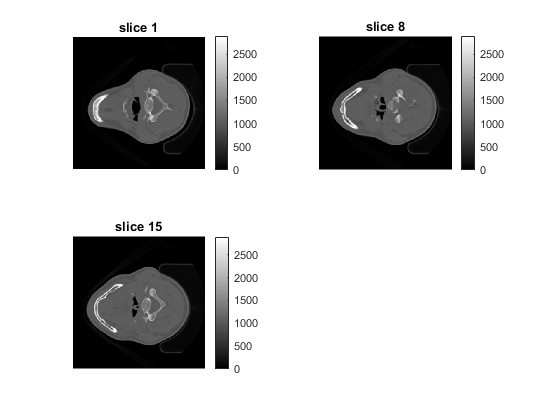

ctvolread

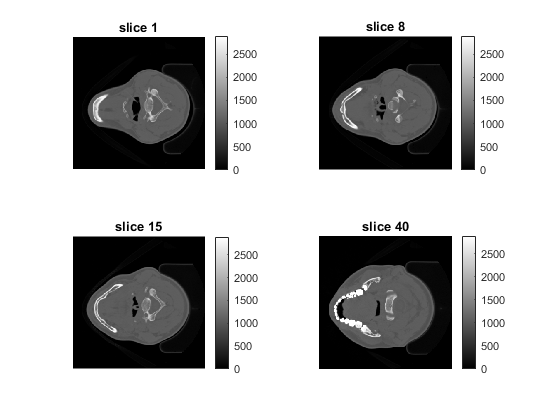

d = 40;

subplot(2,2,4), imshow(ctvol(:,:,d), [0 max(max(ctvol(:,:,8)))]);
title(sprintf('slice %d',d)); axis image; colorbar;

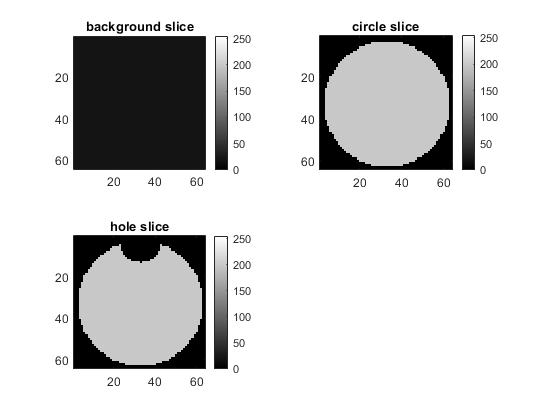

cylmake

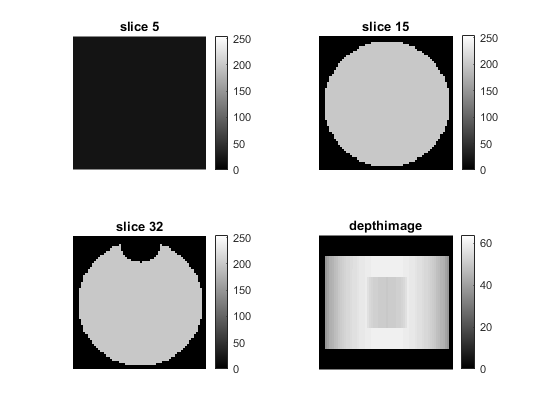

cylvolread

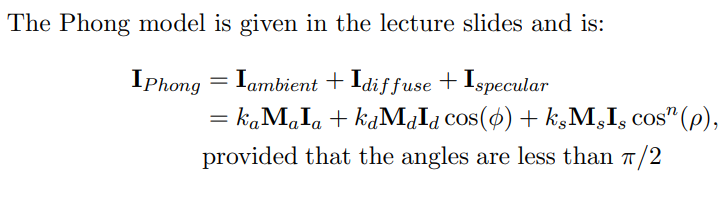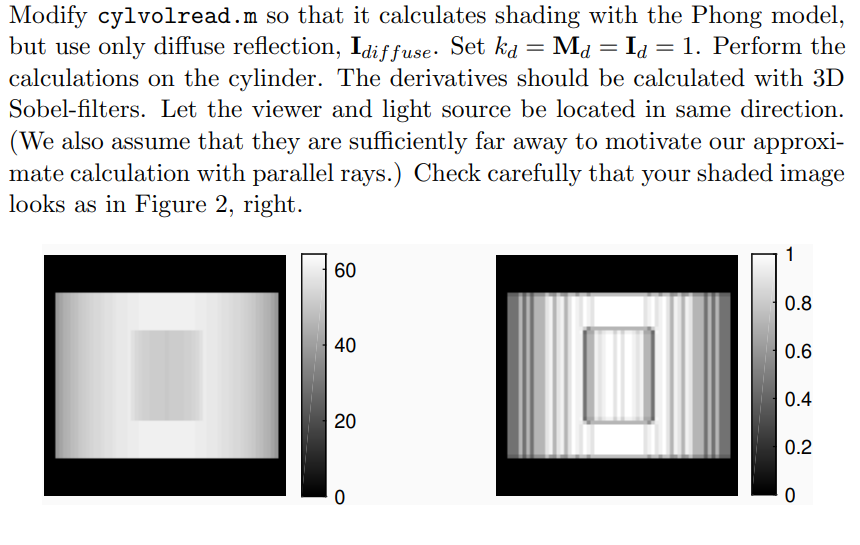

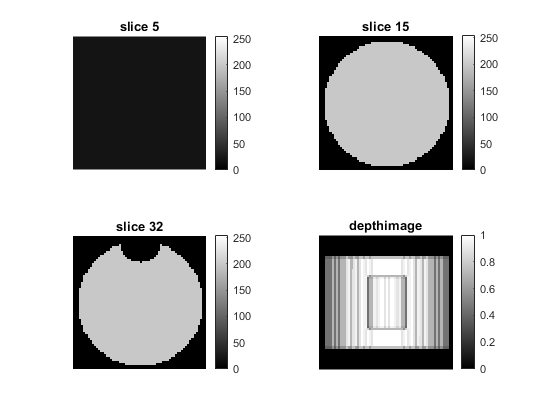

cylvolreadphong_ex3

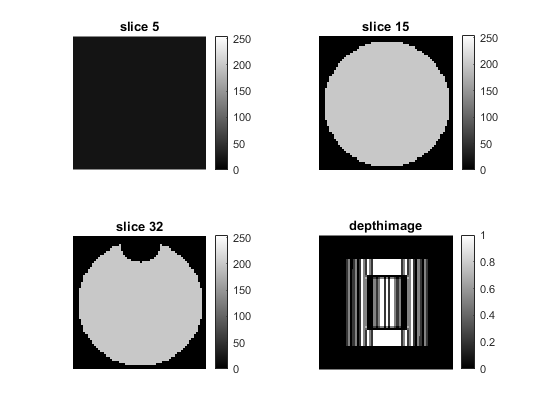

%specify ks kd and n
ks = 1;
kd = 0;
n = 3;
cylvolreadphong_ex4

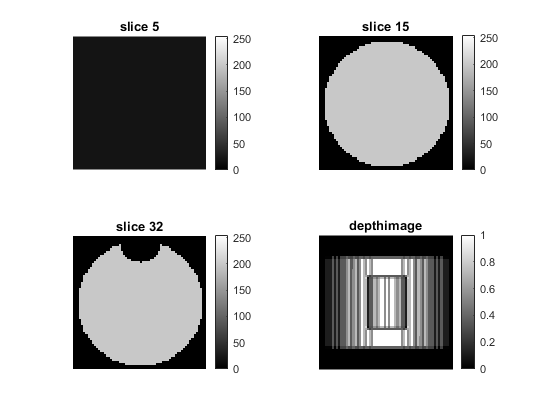


ks = 0.5;
kd = 0.5;
n = 3;
cylvolreadphong_ex4

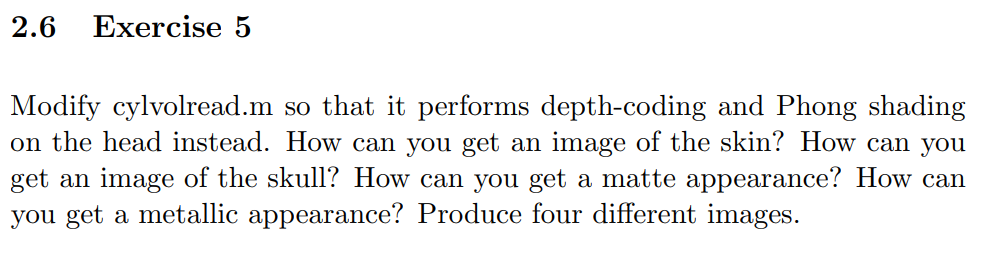

Skin by thresh 1000

skull by thresh 1500

matte if less reflective so set ks to 0, kd 1

metallic if ks high, 1, kd 0

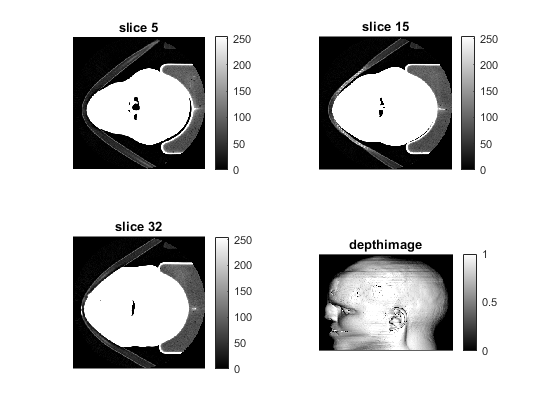

% Set params
kd = 1;
Md = 1;
Id = 1;

ks = 0.1;
n = 3;
Ms = 1;
Is = 1;
thresh = 1000;

cylvolreadphong_ex5

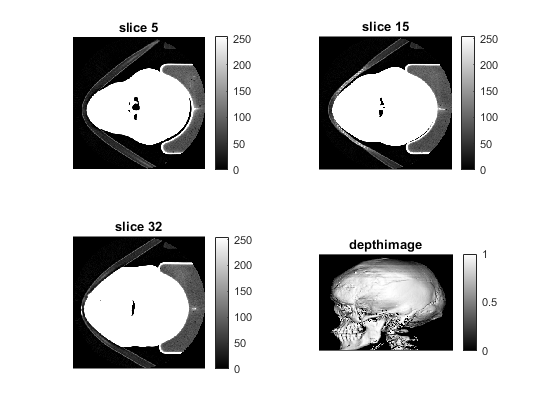


% Set params
ks = 0;
n = 3;
thresh = 1500;

cylvolreadphong_ex5

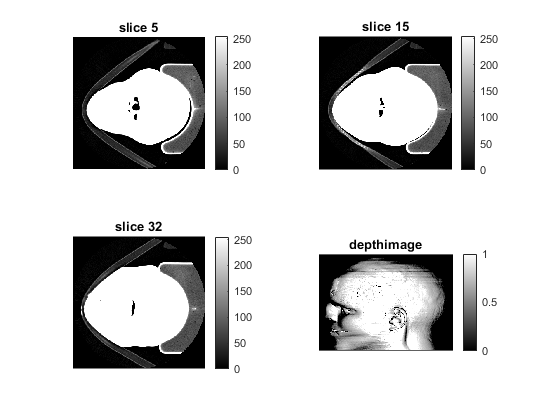


% set params
ks = 1;
n = 3;
thresh = 1000;

cylvolreadphong_ex5

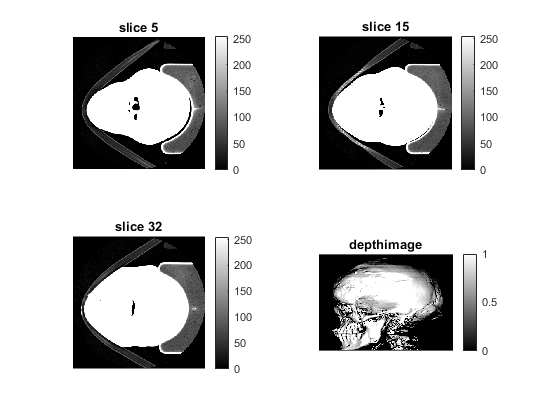


% Set params
ks = 1;
n = 3;
thresh = 1500;

cylvolreadphong_ex5

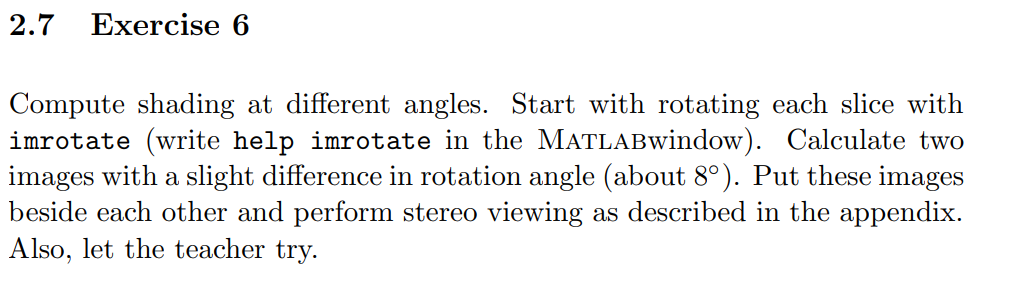

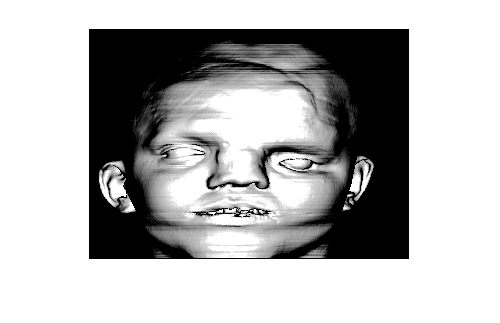

load ctvol.mat;
for i = 1:230
    ctvol(:,:,i) = imrotate(ctvol(:,:,i),-90,'nearest','crop');
end

ctvol_in = ctvol;
thresh = 800;
cylvolreadphong_ex6

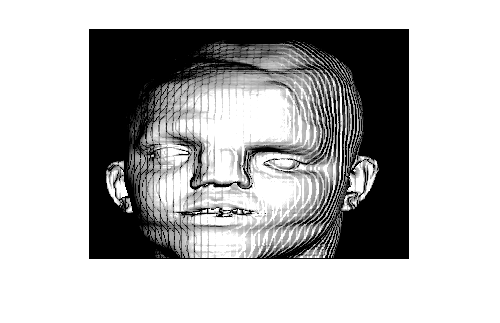


ctvol_rot8 = zeros(320,320,230);
for i = 1:230
    ctvol_rot8(:,:,i) = imrotate(ctvol(:,:,i),8,'nearest','crop');
end
ctvol_in = ctvol_rot8;
cylvolreadphong_ex6

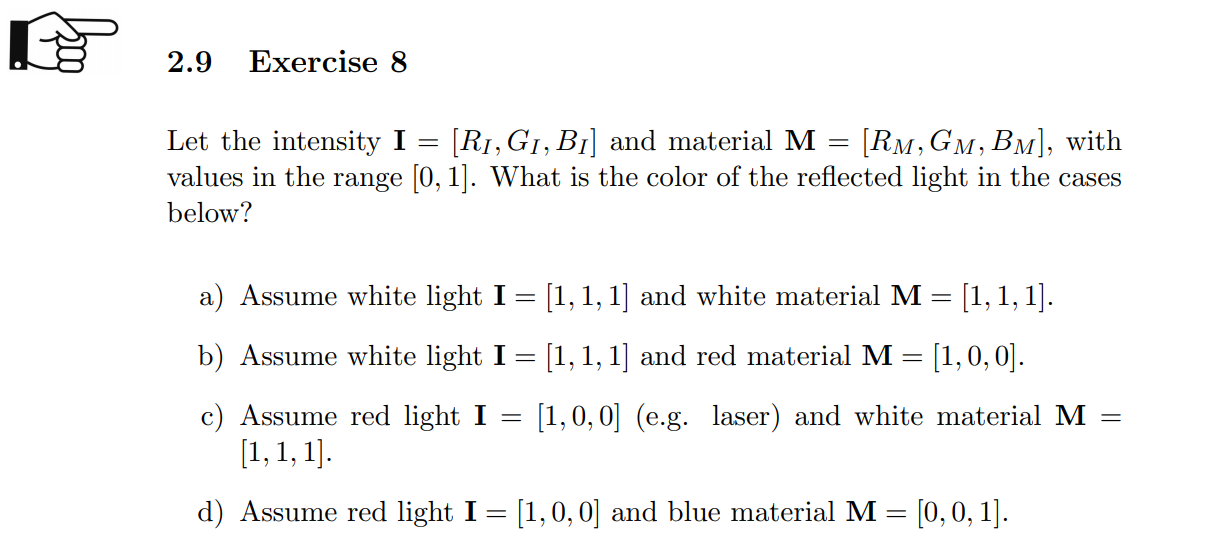

a) White

b) Red

c) Red

d) Black (0,0,0)

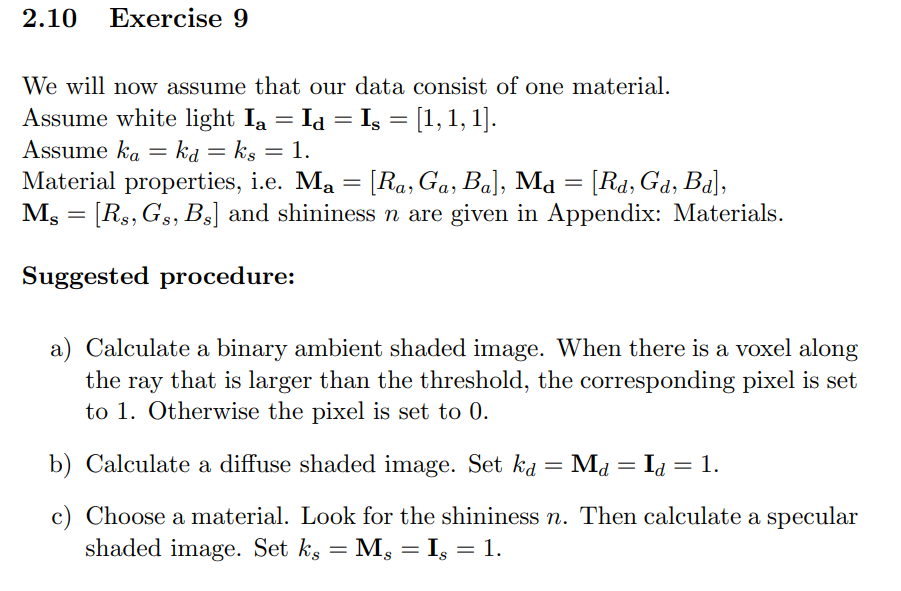

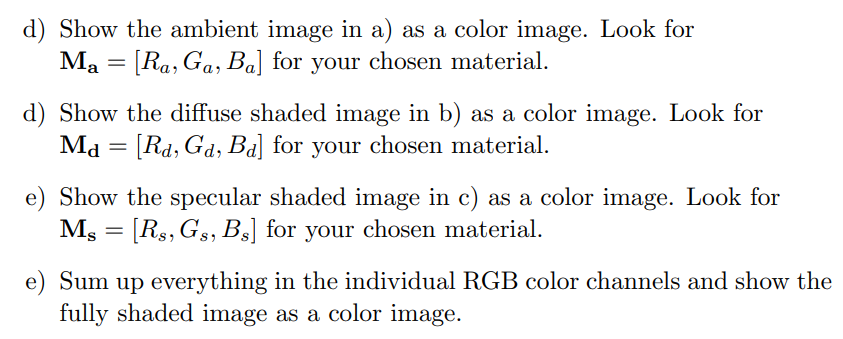

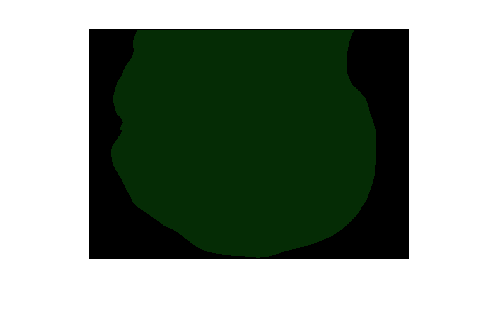

Ma = [0.0215, 0.1745, 0.0215];
Md = [0.07568, 0.61424, 0.07568];
Ms = [0.633,0.727811, 0.633];
n = 32*0.6;
thresh = 800;


% load volume
%------------
load ctvol.mat;

for i = 1:230
    ctvol(:,:,i) = imrotate(ctvol(:,:,i),-45,'nearest','crop');
end

ctvol = double(ctvol);

% check sizes, note that (row,col,z) corresponds to (y,x,z)
%----------------------------------------------------------
siz = size(ctvol);
sizex = siz(2);
sizey = siz(1);
sizez = siz(3);
zmax = sizez;

% Ambient shaded
%--------------------------------------

tmp = zeros(3,3,3);
ambient = zeros(sizez,sizex);

for z = 2 : zmax -1
  for x = 2 : sizex -1
    y=1;
    while (y<sizey) && (ctvol(y,x,z)<thresh)
      y=y+1;
    end
    if ctvol(y,x,z)>=thresh
      ambient(z,x) = 1;
    end
  end
end

% diffuse shaded
%--------------------------------------

tmp = zeros(3,3,3);
diffuse = zeros(sizez,sizex);

for z = 2 : zmax -1
  for x = 2 : sizex -1
    y=1;
    while (y<sizey) && (ctvol(y,x,z)<thresh)
      y=y+1;
    end
    if ctvol(y,x,z)>=thresh
      tmp(:,:,1) = ctvol(y-1:y+1,x-1:x+1,z-1);
      tmp(:,:,2) = ctvol(y-1:y+1,x-1:x+1,z);
      tmp(:,:,3) = ctvol(y-1:y+1,x-1:x+1,z+1);
      
      [grady, gradx, gradz] = gradxyz(tmp);
      grad = [grady, gradx, gradz];
      grad = grad / norm(grad);
      l_vec = [1,0,0];
      
      scalarprod = dot(grad,l_vec);
      diffuse(z,x) = max(scalarprod,0);
    end
  end
end

% specular shaded
%--------------------------------------

tmp = zeros(3,3,3);
specular = zeros(sizez,sizex);

for z = 2 : zmax -1
  for x = 2 : sizex -1
    y=1;
    while (y<sizey) && (ctvol(y,x,z)<thresh)
      y=y+1;
    end
    if ctvol(y,x,z)>=thresh
      tmp(:,:,1) = ctvol(y-1:y+1,x-1:x+1,z-1);
      tmp(:,:,2) = ctvol(y-1:y+1,x-1:x+1,z);
      tmp(:,:,3) = ctvol(y-1:y+1,x-1:x+1,z+1);
      
      [grady, gradx, gradz] = gradxyz(tmp);
      grad = [grady, gradx, gradz];
      grad = grad / norm(grad);
      l_vec = [1,0,0];
      v_vec = l_vec;
      
      % find r
      % https://math.stackexchange.com/questions/13261/how-to-get-a-reflection-vector
      d = -l_vec;
      r_vec = d-2*(dot(d,grad)*grad); 
      
      scalarprod = dot(grad,l_vec);
      specular(z,x) = (dot(r_vec,v_vec))^n;
    end
  end
end


ambientrgb = zeros(230,320,3);
ambientrgb(:,:,1) = Ma(1)*ambient;
ambientrgb(:,:,2) = Ma(2)*ambient;
ambientrgb(:,:,3) = Ma(3)*ambient;

figure
imshow(ambientrgb)

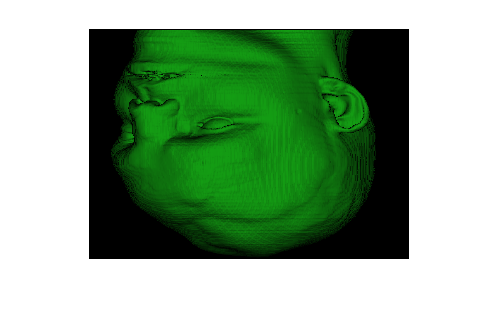



diffusergb = zeros(230,320,3);
diffusergb(:,:,1) = Md(1)*diffuse;
diffusergb(:,:,2) = Md(2)*diffuse;
diffusergb(:,:,3) = Md(3)*diffuse;

figure
imshow(diffusergb)

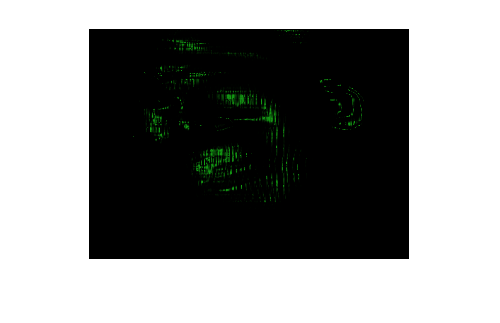


specularrgb = zeros(230,320,3);
specularrgb(:,:,1) = Md(1)*specular;
specularrgb(:,:,2) = Md(2)*specular;
specularrgb(:,:,3) = Md(3)*specular;

figure
imshow(specularrgb)

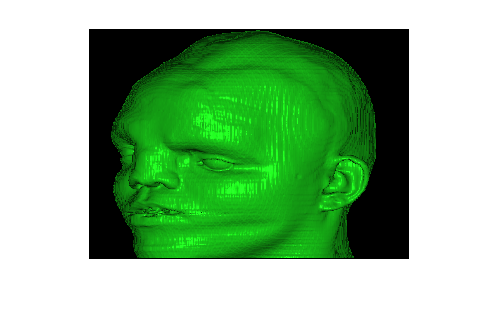


fullrgb = ambientrgb+diffusergb+specularrgb;
figure
imshow(flip(abs(fullrgb)))